## SO3 so3 变换的研究

w1 = pi*rand([3,1]);
w2 = pi*rand([3,1]);

R1 = rod2dcm(w1');
R2 = rod2dcm(w2');

v = [1;0;0];
v1 = R1*v;
v2 = R2*v;

数乘封闭的验证

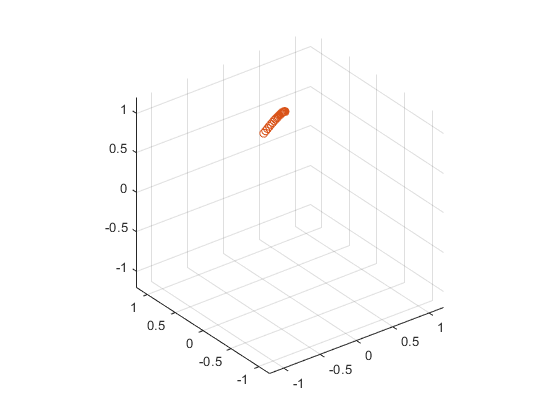

scatter3([v1(1), v2(1)], [v1(2), v2(2)], [v1(3), v2(3)]), hold on;
axis equal;
lim = 1.2;
xlim([-lim, lim]);
ylim([-lim, lim]);
zlim([-lim, lim]);

R = R2*R1';
w = dcm2rod(R);
t = linspace(0, 1, 20);

wt = [];
for i=1:length(t)
    wt = [wt; w*t(i)];
end

Rt = rod2dcm(wt);
ps = [];
for i = 1:length(t)
    ps = [ps, Rt(:,:,i)*R1*v];
end
scatter3(ps(1,:), ps(2,:), ps(3,:)), hold off

加法不封闭的验证

w3 = w1+w2

w3 =     5.3940
    3.6231
    1.7613


R3 = rod2dcm(w3')

R3 =     0.2993    0.9198    0.2537
    0.7677   -0.3901    0.5084
    0.5666    0.0426   -0.8229


w4 = dcm2rod(R1*R2)

w4 =    -0.2135   -0.8229   -0.3364


w5 = dcm2rod(R2*R1)

w5 =    -0.9113    0.0674   -0.0309



p12 = R1*R2*v;
p3 = R3*v;
p4 = R2*R1*v

p4 =     0.9940
   -0.0332
    0.1041


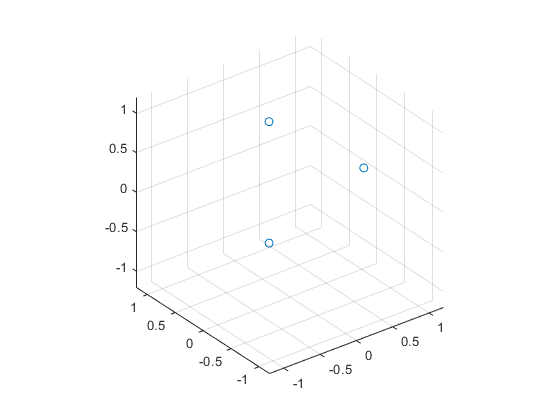

scatter3([p12(1), p3(1), p4(1)], [p12(2), p3(2), p4(2)], [p12(3), p3(3), p4(3)])
axis equal;
lim = 1.2;
xlim([-lim, lim]);
ylim([-lim, lim]);
zlim([-lim, lim]);


w3 = [w1(1)*w2(1); w1(2)*w2(2); w1(3)*w2(3)]

w3 =     7.2598
    3.2447
    0.0866


R3 = rod2dcm(w3')

R3 =     0.6720    0.7361   -0.0814
    0.7307   -0.6411    0.2348
    0.1206   -0.2173   -0.9686


w4 = dcm2rod(R1*R2)

w4 =    -0.2135   -0.8229   -0.3364


w5 = dcm2rod(R2*R1)

w5 =    -0.9113    0.0674   -0.0309



p12 = R1*R2*v;
p3 = R3*v;
p4 = R2*R1*v

p4 =     0.9940
   -0.0332
    0.1041


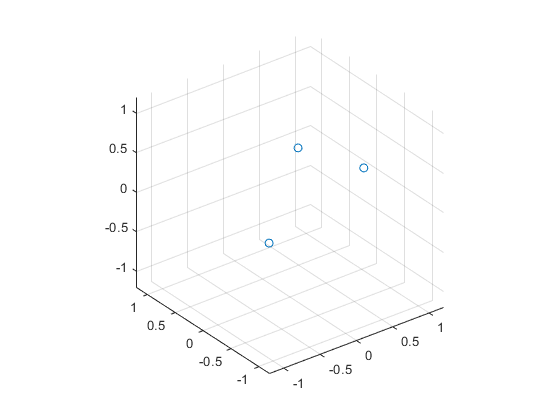

scatter3([p12(1), p3(1), p4(1)], [p12(2), p3(2), p4(2)], [p12(3), p3(3), p4(3)])
axis equal;
lim = 1.2;
xlim([-lim, lim]);
ylim([-lim, lim]);
zlim([-lim, lim]);

小角度加法不封闭验证

e = 0.1;
w1 = e*w1;
w2 = e*w2;
w3 = w1+w2;
R12 = rod2dcm(w1')*rod2dcm(w2')

R12 =     0.6808    0.5980   -0.4230
    0.0547    0.5344    0.8435
    0.7304   -0.5974    0.3311


R3 = rod2dcm(w3')

R3 =     0.7766    0.5114   -0.3679
    0.0266    0.5569    0.8302
    0.6294   -0.6545    0.4189


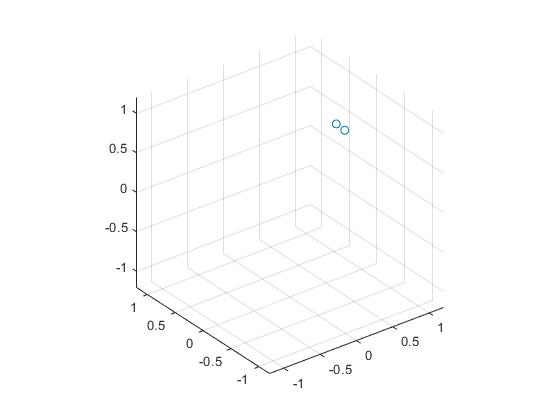

p12 = R12*v;
p3 = R3*v;
scatter3([p12(1), p3(1)], [p12(2), p3(2)], [p12(3), p3(3)])
axis equal;
lim = 1.2;
xlim([-lim, lim]);
ylim([-lim, lim]);
zlim([-lim, lim]);

## optimization in so3

num = 3;
x = 10*rand([3, num]);
wtar = [pi,0,0]

wtar =     3.1416         0         0


Rtarget = rod2dcm(wtar)

Rtarget =     1.0000         0         0
         0   -0.8160    0.5781
         0   -0.5781   -0.8160


y = Rtarget*x

y =     4.0982    8.9894
    1.5541   -2.1910
   -4.3282   -3.0249


x = x + 0.001*rand([3, num]);
y = y + 0.001*rand([3, num]);

R = eye(3);
iteration = 10;
alpha = 0.1;
e = []


e =

     []



for i=1:iteration
    ts = [];
    for j=1:num
        t = -vec2ssm(R*x(:,j))*2*(R*x(:,j)-y(:,j));
        ts = [ts t];
    end
    M = zeros(3);
    tt = zeros([3,1]);
    beta = sum((R*x-y).*(R*x-y));
    for k=1:num
        M = M+ts(:,k)*ts(:,k)';
        tt = tt-ts(:,k)*beta(k);
    end
    sts = sum(ts,2)
    tend = linsolve(M, tt)'
    R = rod2dcm(tend)*R;
    e = [e sum(beta)];

end

sts =   -40.5865
  147.7776
 -100.3477


tend =    -3.4462   -2.2217   -0.6078


sts =   -47.0261
   70.8957
 -154.6350


tend =    -0.9491   -0.5991    0.6511


sts =   -23.2148
   -3.7561
  -31.2257


tend =     0.1422   -0.0215    0.0234


sts =    -0.1590
  -10.1666
    5.8622


tend =    -4.1933    0.1262    0.0484


sts =   -28.2159
  161.4412
  -87.1665


tend =     3.0607   -0.3763   -0.1450


sts =    -2.4920
  -41.7357
   19.7140


tend =    -0.1114    0.0900   -0.0883


sts =   -29.8852
   -2.7930
  -40.8031


tend =     0.0719   -0.1217    0.1194


sts =    -4.5312
  -56.9112
   24.2034


tend =     0.6458    0.0302   -0.2001


sts =    52.7583
   50.6234
   58.4829


tend =    -0.0916    0.0567   -0.3751


sts =   -20.1288
   78.4263
  -95.6827


tend =    -6.4458   -2.4550   -0.2154


w = dcm2rod(R)

w =     0.1816    0.0000    0.0000


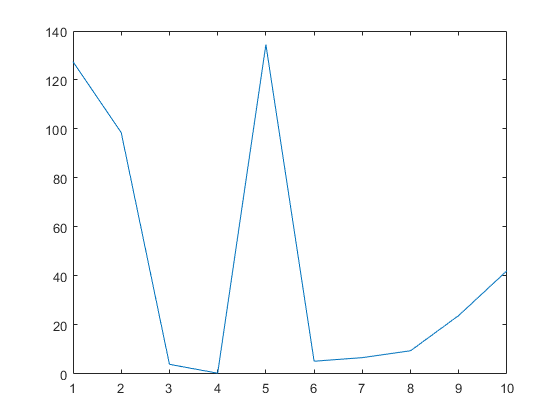

plot(e)

scatter3(x(1,:), x(2,:), x(3,:), 'blue'); hold on
scatter3(y(1,:), y(2,:), y(3,:), 'black'); hold on

rnum = 20;
angle = norm(w);
e = w/angle;
k = linspace(0, angle, rnum);
ps = zeros([3, num, rnum]);
for i=1:rnum
    w1 = k(i)*e
    R = rod2dcm(w1);
    ps(:,:,i) = R*x;
end

w1 =      0     0     0


w1 =     0.0096    0.0000    0.0000


w1 =     0.0191    0.0000    0.0000


w1 =     0.0287    0.0000    0.0000


w1 =     0.0382    0.0000    0.0000


w1 =     0.0478    0.0000    0.0000


w1 =     0.0573    0.0000    0.0000


w1 =     0.0669    0.0000    0.0000


w1 =     0.0764    0.0000    0.0000


w1 =     0.0860    0.0000    0.0000


w1 =     0.0956    0.0000    0.0000


w1 =     0.1051    0.0000    0.0000


w1 =     0.1147    0.0000    0.0000


w1 =     0.1242    0.0000    0.0000


w1 =     0.1338    0.0000    0.0000


w1 =     0.1433    0.0000    0.0000


w1 =     0.1529    0.0000    0.0000


w1 =     0.1624    0.0000    0.0000


w1 =     0.1720    0.0000    0.0000


w1 =     0.1816    0.0000    0.0000


ps

ps = ps(:,:,1) =

    4.0987    8.9894
    1.2347    3.5365
    4.4305    1.2019


ps(:,:,2) =

    4.0987    8.9894
    1.3191    3.5588
    4.4061    1.1341


ps(:,:,3) =

    4.0987    8.9894
    1.4031    3.5799
    4.3801    1.0659


ps(:,:,4) =

    4.0987    8.9894
    1.4865    3.5995
    4.3525    0.9973


ps(:,:,5) =

    4.0987    8.9895
    1.5693    3.6179
    4.3234    0.9284


ps(:,:,6) =

    4.0987    8.9895
    1.6514    3.6350
    4.2926    0.8593


ps(:,:,7) =

    4.0987    8.9895
    1.7329    3.6507
    4.2604    0.7898


ps(:,:,8) =

    4.0987    8.9895
    1.8137    3.6650
    4.2266    0.7202


ps(:,:,9) =

    4.0987    8.9895
    1.8937    3.6780
    4.1914    0.6504


ps(:,:,10) =

    4.0987    8.9895
    1.9730    3.6897
    4.1547    0.5805


ps(:,:,11) =

    4.0987    8.9895
    2.0514    3.7000
    4.1165    0.5104


ps(:,:,12) =

    4.0987    8.9895
    2.1289    3.7090
    4.0770    0.4403


ps(:,:,13) =

    4.0987    8.9895
    2.2055    3.7167


for i=2:rnum-1
    scatter3(ps(1,:,i), ps(2,:,i), ps(3,:,i),'green'); hold on
end
axis equal
hold on
wtar

wtar =     3.1416         0         0


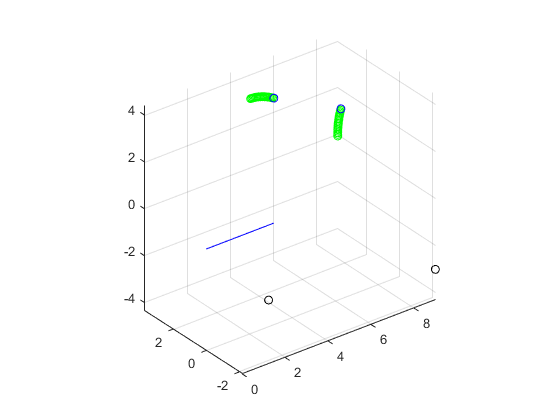

plot3([0, wtar(1)], [0, wtar(2)], [0, wtar(3)], 'blue')
hold off